# Redes Neuronales

# Aprendizaje no Supervisado

# Tarea 9

# Dataset Path-Based1

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-08-29

tic
clc;
clear;
close all;
rng(0);
warning("off","all");

% Carga y limpieza de datos
datos = importdata("pathbased.txt");
X = datos(:,1:2);

% ---------------------------------------
% k-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-means")

k-means

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 8

k = 8

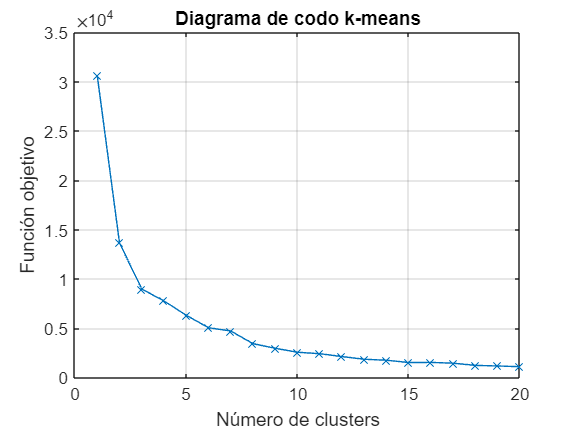

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    Jkm(i) = sum(SumD);
    Kkm(i) = i;
end

figure;
plot(Kkm, Jkm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

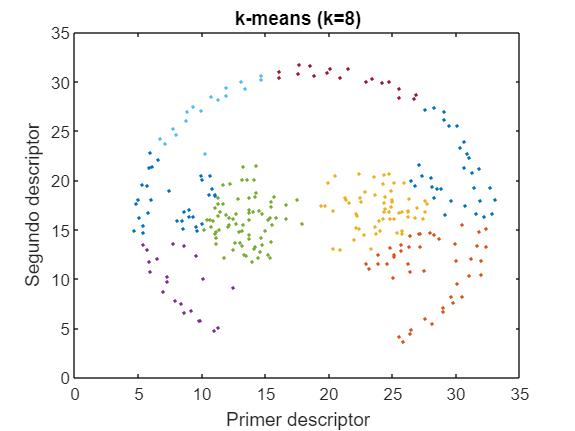


% Clustering
idx = kmeans(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-means (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-means")

Valores de métricas k-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 3.0668

SSB = 8.9472

WB = 2.7422

SIL = 0.5409



% ---------------------------------------
% k-medoids
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-medoids")

k-medoids

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 8

k = 8

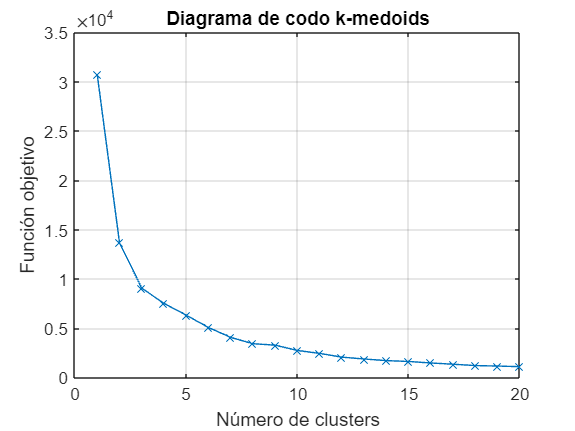

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    Jkmd(i) = sum(SumD);
    Kkmd(i) = i;
end

figure;
plot(Kkmd, Jkmd,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

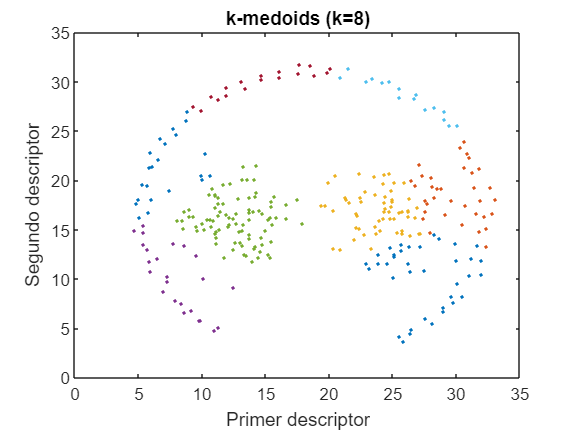


% Clustering
idx = kmedoids(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-medoids (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-medoids")

Valores de métricas k-medoids

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 3.0575

SSB = 8.9552

WB = 2.7314

SIL = 0.5684


% ---------------------------------------
% DBSCAN
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("DBSCAN")

DBSCAN

fprintf("---------------------------------------")

---------------------------------------

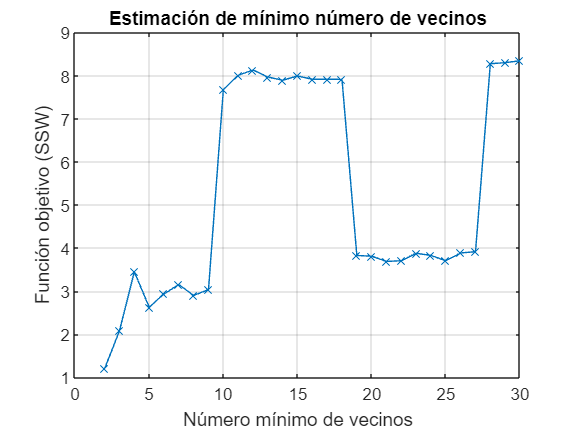


min_n = 19;
gmin_n = 2:1:30;

% Estimación número mínimo de vecinos
for i = 1:length(gmin_n)
    rng(0);
    min_ng = gmin_n(i);
    ep = clusterDBSCAN.estimateEpsilon(X,min_ng,min_ng);
    idx = dbscan(X,ep,min_ng);
    [SSWdb(i) SSBdb(i) WBdb(i) SILdb(i)] = MetricasNoSupervisado(X(idx>0,:),idx(idx>0));
    Kdb(i)=min_ng;
end

figure;
plot(Kdb,SSWdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (SSW)");
title("Estimación de mínimo número de vecinos");

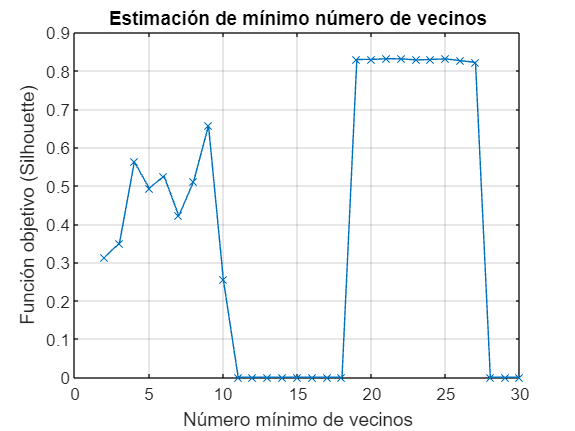


figure;
plot(Kdb,SILdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (Silhouette)");
title("Estimación de mínimo número de vecinos");



% Gráfica k-NN (Nearest Neigbor)
min_n

min_n = 19

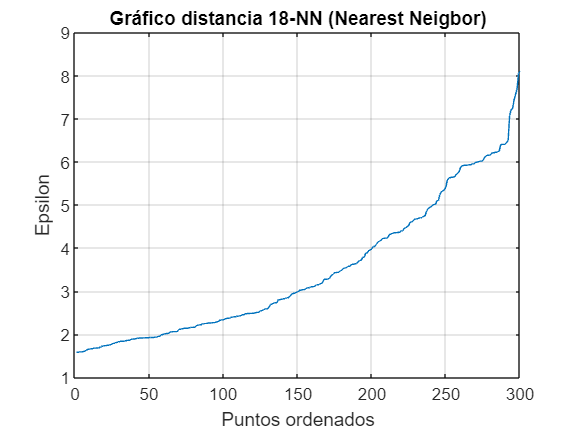

figure;
kD = pdist2(X,X,'euc','Smallest',min_n-1);
plot(sort(kD(end,:)));
title(strcat("Gráfico distancia ",string(min_n-1),"-NN (Nearest Neigbor)"));
xlabel("Puntos ordenados");
ylabel("Epsilon");
grid;


% Clustering
rng(0);
ep = clusterDBSCAN.estimateEpsilon(X,min_n,min_n)

ep = 3.4482

idx = dbscan(X,ep,min_n);
clusters = unique(idx(idx>0));
num_clusters = length(clusters)

num_clusters = 2

anomalias = length(idx(idx<=0));

if (anomalias>0)
    fprintf(strcat("Existen ",string(anomalias)," anomalías"));
else
    fprintf("No existen anomalías");
end

Existen 71 anomalías

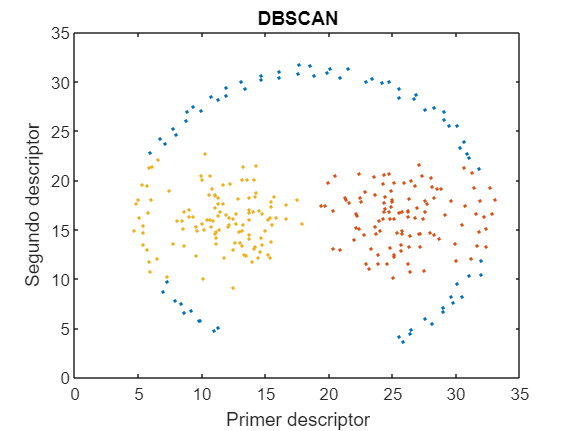


% Visualización de datos
figure;
for i=min(idx):max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("DBSCAN"));


% Métricas
fprintf("Valores de métricas DBSCAN")

Valores de métricas DBSCAN

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(idx>0,:),idx(idx>0))

SSW = 3.8258

SSB = 7.3168

WB = 1.0458

SIL = 0.8296


% ---------------------------------------
% Clustering Jerárquico
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Clustering Jerárquico")

Clustering Jerárquico

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 10

k = 10

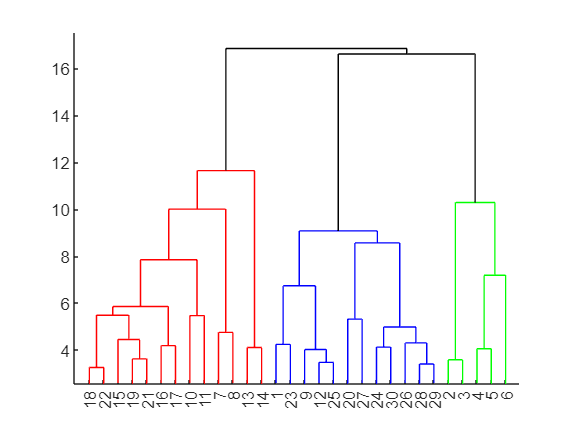

rng(0);

% Dendrograma
tree = linkage(X,"average","euclidean");
figure;
dendrogram(tree,"ColorThreshold","default")

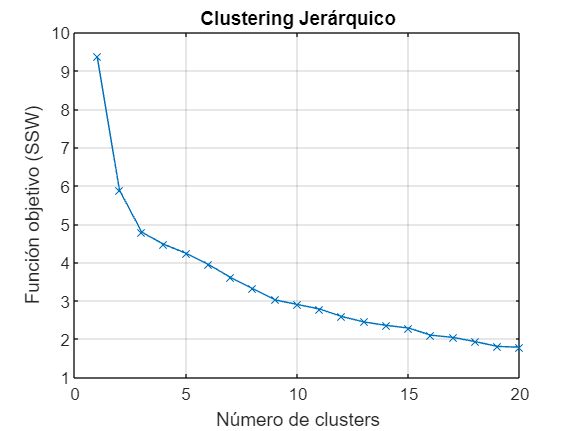


% Diagrama de codo
for i =1:n
    idx = cluster(tree,"maxclust",i);
    [SSWhc(i) SSBhc(i) WBhc(i) SILhc(i)] = MetricasNoSupervisado(X,idx);
    Khc(i)=i;
end

figure;
plot(Khc,SSWhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Clustering Jerárquico");

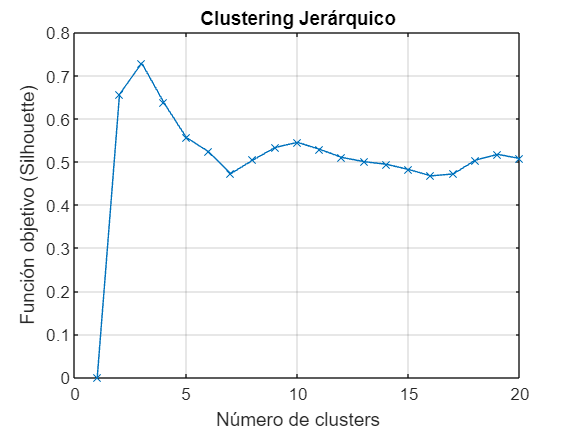


figure;
plot(Khc,SILhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (Silhouette)");
title("Clustering Jerárquico");

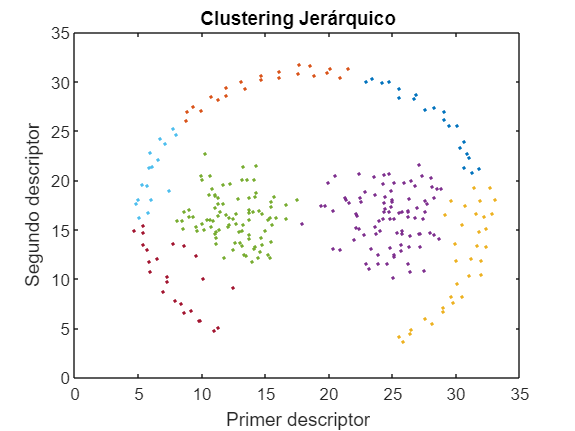


% Clusterización
idx = cluster(tree,"maxclust",k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title("Clustering Jerárquico");


% Métricas
fprintf("Valores de métricas Clustering Jerárquico")

Valores de métricas Clustering Jerárquico

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 2.8998

SSB = 8.9096

WB = 3.2547

SIL = 0.5451


% ---------------------------------------
% Fuzzy c-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Fuzzy c-means")

Fuzzy c-means

fprintf("---------------------------------------")

---------------------------------------


n=20

n = 20

c=8

c = 8

rng(0);

% Diagrama de codo
for i =1:n
    [centers,U] = fcm(X,i);
    Ut=U';
    idx= ones(length(Ut),1);
    maxU = max(U)';

    for j = 1:i
        s = Ut(:,j);
        f = find(s==maxU);
        idx(f)=j;
    end

    [SSWfcm(i) SSBfcm(i) WBfcm(i) SILfcm(i)] = MetricasNoSupervisado(X,idx);
    Kfcm(i)=i;
end

Iteration count = 1, obj. fcn = 0.466788
Iteration count = 2, obj. fcn = 0.109227
Iteration count = 3, obj. fcn = 0.102142
Iteration count = 4, obj. fcn = 0.066180
Iteration count = 5, obj. fcn = 0.002216
Iteration count = 6, obj. fcn = 0.000000
Iteration count = 7, obj. fcn = 0.000000
Minimum improvement reached.
Iteration count = 1, obj. fcn = 18384.201318
Iteration count = 2, obj. fcn = 15166.419973
Iteration count = 3, obj. fcn = 14302.375565
Iteration count = 4, obj. fcn = 11763.969635
Iteration count = 5, obj. fcn = 10407.118456
Iteration count = 6, obj. fcn = 10288.412997
Iteration count = 7, obj. fcn = 10284.001518
Iteration count = 8, obj. fcn = 10283.833855
Iteration count = 9, obj. fcn = 10283.821961
Iteration count = 10, obj. fcn = 10283.820446
Iteration count = 11, obj. fcn = 10283.820213
Iteration count = 12, obj. fcn = 10283.820176
Iteration count = 13, obj. fcn = 10283.820170
Minimum improvement reached.
Iteration count = 1, obj. fcn = 12929.092660
Iteration count = 2, 

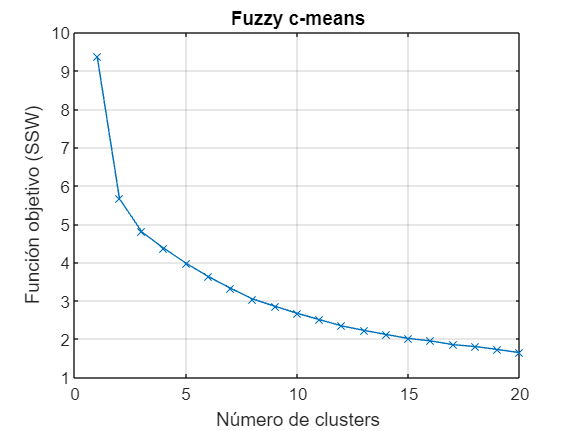


figure;
plot(Kfcm,SSWfcm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Fuzzy c-means");


% Clusterización
[centers,U] = fcm(X,c);

Iteration count = 1, obj. fcn = 5060.976732
Iteration count = 2, obj. fcn = 3779.044245
Iteration count = 3, obj. fcn = 3551.360634
Iteration count = 4, obj. fcn = 3089.645932
Iteration count = 5, obj. fcn = 2762.812311
Iteration count = 6, obj. fcn = 2573.275765
Iteration count = 7, obj. fcn = 2447.864350
Iteration count = 8, obj. fcn = 2300.117830
Iteration count = 9, obj. fcn = 2116.062520
Iteration count = 10, obj. fcn = 2042.681554
Iteration count = 11, obj. fcn = 2008.529127
Iteration count = 12, obj. fcn = 1978.305485
Iteration count = 13, obj. fcn = 1950.809631
Iteration count = 14, obj. fcn = 1926.855012
Iteration count = 15, obj. fcn = 1908.704646
Iteration count = 16, obj. fcn = 1896.529472
Iteration count = 17, obj. fcn = 1888.684735
Iteration count = 18, obj. fcn = 1883.538192
Iteration count = 19, obj. fcn = 1879.899538
Iteration count = 20, obj. fcn = 1877.025766
Iteration count = 21, obj. fcn = 1874.532215
Iteration count = 22, obj. fcn = 1872.251392
Iteration count = 2

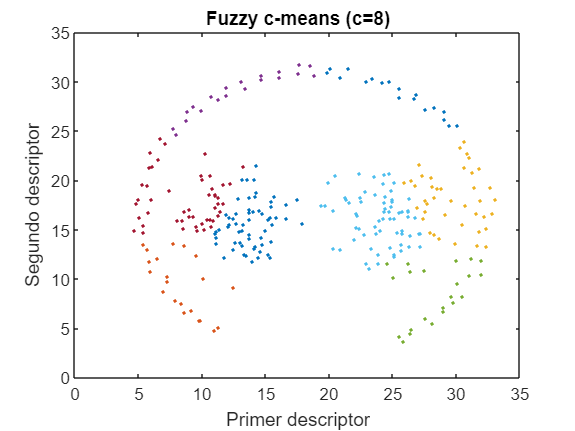

Ut=U';
idx= ones(length(Ut),1);
maxU = max(U)';

for i = 1:c
    s = Ut(:,i);
    f = find(s==maxU);
    idx(f)=i;
end

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("Fuzzy c-means (c=",string(c),")"));


% Métricas
fprintf("Valores de métricas Fuzzy c-means")

Valores de métricas Fuzzy c-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 3.0472

SSB = 8.9276

WB = 2.7306

SIL = 0.5356


toc

Elapsed time is 3.211290 seconds.
